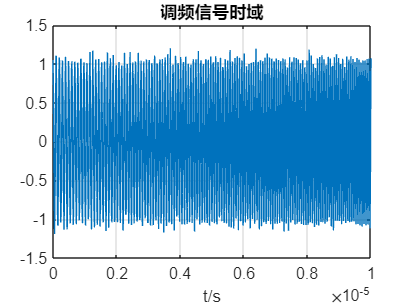

close all
clear
clc

fs=5e8;%采样频率
T=1e-5;%时宽
B=6e6;%带宽
mu=B/T;%调频率
n=round(T*fs);%采样点个数
t=linspace(0,T,n);
f0=10e6;%起始频率
s=exp(2j*pi*(f0*t+0.5*mu*t.^2));
SNR=20;%信噪比
s=awgn(s,SNR);%添加一定信噪比的高斯白噪声

figure
plot(t,real(s))%时域图
title("调频信号时域")
xlabel("t/s")
xlim([0,T])
grid on

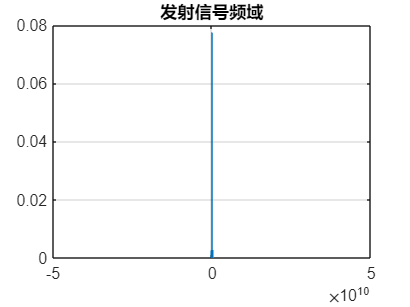


figure
S=fftshift(fft(real(s))./n);
f=linspace(-fs/2,fs/2-1,n);%频域横坐标，注意奈奎斯特采样定理，最大原信号最大频率不超过采样频率的一半
plot(f,abs(S))%频域图
title("发射信号频域")
xlim([-50e9,50e9])
grid on

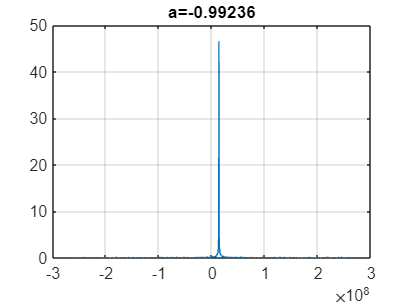


k=B/fs;%归一化调频斜率
a=acot(-k)/(pi/2);%以归一化调频斜率估计阶次
% a=pi/2+atan(n-1)*mu/fs^2;
% for a=0.9:0.01:1
figure
S=myfrft(s,a);
f=linspace(-fs/2,fs/2-1,n);%频域横坐标，注意奈奎斯特采样定理，最大原信号最大频率不超过采样频率的一半
plot(f,abs(S))%频域图
% title("发射信号时频域")
% xlim([0,fs/2-1])
title("a="+num2str(a))
grid on

% end

fh_predict=abs(f(abs(S)==max(abs(S)))*csc(a*pi/2));%估计的中心频率
f0=fh_predict-B/2;%估计的起始频率
